# Lab10: Identification of statistical characteristics to construct tracking filter of a moving object

Team1: Dmitry Shadrin, Eugenii Israelit, Sergey Golovanov @Skoltech

Part I. Noise statistics identification

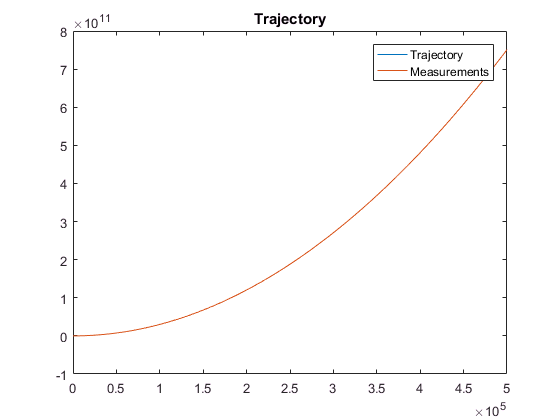

clc; clear; close all;
addpath('functions/');

n = 500000;
sigmaA = 3;
sigmaN = 10;
x1 = 5;
v1 = 1;
t = 1; 
q = 6;
Acc = q + normrnd(0, sigmaA, 1, n );
Noise = normrnd(0, sigmaN, 1, n );
[ X, M  ] = calcTrajectory( Acc, Noise, x1, v1, t);

plot(1:n, X, 1:n, M);
    title('Trajectory')
    legend('Trajectory', 'Measurements');

3. Identifying bias, standard deviation and standard deviation using measurements

V = M(3:end) - 2*M(2:end-1) + M(1:end-2);
P = M(4:end) - 3*M(2:end-2) + 2*M(1:end-3);

qCalc = mean(V) / t^2

qCalc = 6.0028


eV = mean ( (V - qCalc*t^2).^2 );
eP = mean ( (P - 3*qCalc*t^2).^2 );

varianceA = ( (3/7)*eP - eV ) / t^4;
varianceN = eV/6 - (1/12) * varianceA * t^4;

sigmaACalc = sqrt(varianceA)

sigmaACalc = 3.0103

sigmaNCalc = sqrt(varianceN)

sigmaNCalc = 10.0053

Part II. Tracking filter of a moving object on the basis of noise statistics identification and sensitivity analysis of assimilation output to choice of noise statistics

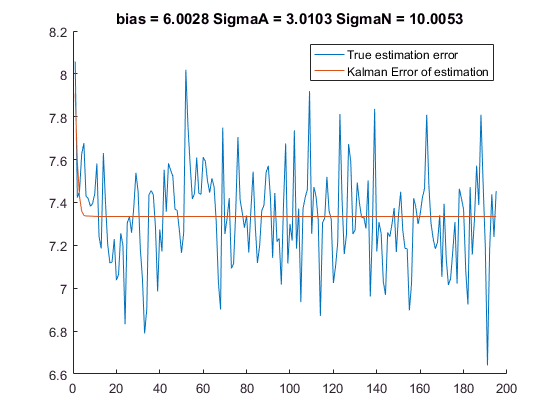

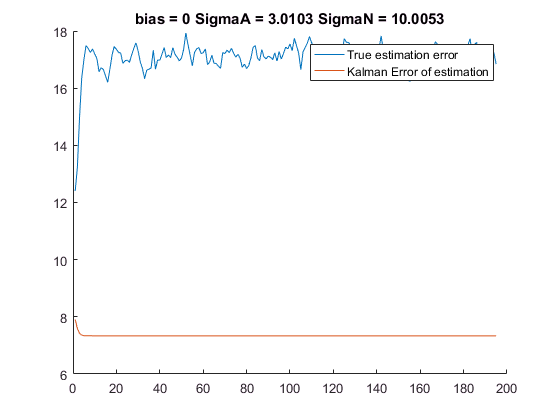

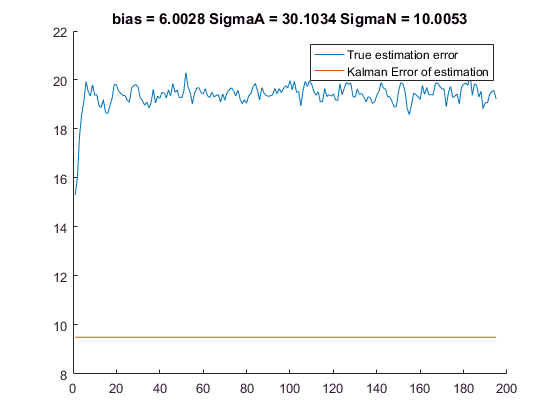

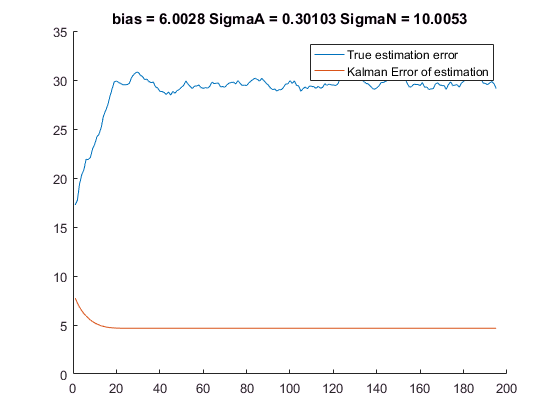

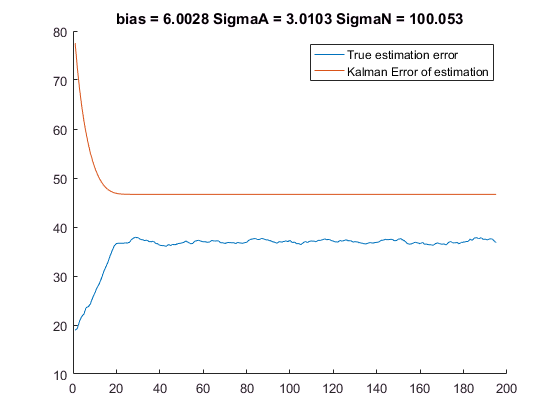

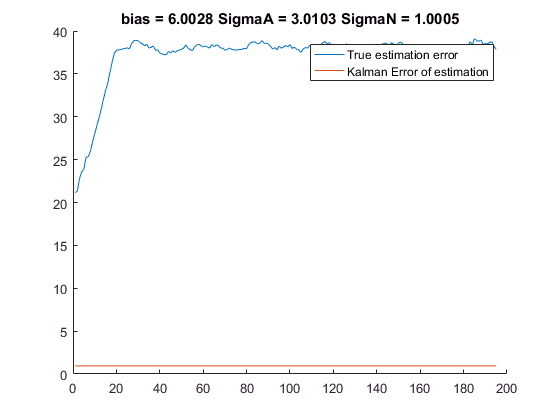

clear X; clear M; clear Acc, clear Noise; clear P; clear V;

n = 200;
x1 = 2;
v1 = 0;

G = [(t^2)/2; t];
F = [1 t; 0 1];
H = [1 0];
P = [10^10 0; 0 10^10];

m = 500;
ErrSum = zeros(1, n);

conditions = [  qCalc, sigmaACalc, sigmaNCalc;
                0, sigmaACalc, sigmaNCalc;
                qCalc, sigmaACalc*10, sigmaNCalc;
                qCalc, sigmaACalc/10, sigmaNCalc;
                qCalc, sigmaACalc, sigmaNCalc*10;
                qCalc, sigmaACalc, sigmaNCalc/10; ];
            
                
for j=1:6
    for i = 1:m
      Acc = normrnd(0, sigmaA, 1, n) + q;
      Noise = normrnd(0, sigmaN, 1, n);
      [ X, Z ] = calcTrajectory( Acc, Noise, x1, v1, t);
      [ Xk, SigmaX ] = calcKalmanLab10(Z, conditions(j,2), conditions(j,3), x1, v1, F, G, H, P, conditions(j,1) );
      ErrCur = ( X - Xk(1,:) ).^2;
      ErrSum = ErrSum + ErrCur;
    end
    FinalError = ( ErrSum./m ).^0.5;
    
    figure; hold on;
        plot(FinalError(6:end));
        plot(SigmaX(6:end));
        title(['bias = ', num2str(conditions(j,1)), ' SigmaA = ', num2str(conditions(j,2)), ' SigmaN = ', num2str(conditions(j,3)) ]);
        legend('True estimation error', 'Kalman Error of estimation');   
end